clc; clear all; close all;

freq = 35;

sensorArray = audioDeviceReader("Device","IN 1-4 (2- BEHRINGER UMC 404HD 192k)", ...
    "Driver","DirectSound","NumChannels",4,"SampleRate",192000,"BitDepth",'16-bit integer')

sensorArray =   audioDeviceReader with properties:

             Driver: 'DirectSound'
             Device: 'IN 1-4 (2- BEHRINGER UMC 404HD 192k)'
        NumChannels: 4
    SamplesPerFrame: 1024
         SampleRate: 192000

  Show all properties



% audioFromDevice=sensorArray() % gets one frame of data from device.
                                % samples per frame can be specified, is
                                % the "buffer" which can be defined and is
                                % the device record start time latency.
                                
setup(sensorArray)

Error using audioDeviceReader/setup
PortAudio Error: Unanticipated host error


Error in audioDeviceReader/setupImpl


fileWriter = dsp.AudioFileWriter('hydrophones.wav','FileFormat','WAV',"SampleRate",192000);

disp("Record start")

tic

while toc<2.5
    
    acquiredAudio=sensorArray();
    
    fileWriter(acquiredAudio);
    
end

disp("Record end")

release(sensorArray)

release(fileWriter)


[data, Fs]=audioread('hydrophones.wav');


t = 0:1/Fs:(length(data)-1)/Fs;

% figure(1);
% for i = 1:4
%     plot(t,data(:,i)); hold on;
% end
% hold off; legend({'Channel 1','Channel 2','Channel 3','Channel 4'});

sensor_A = data(:,1);
sensor_B = data(:,2);
sensor_C = data(:,3);
sensor_D = data(:,4);

fs = 192000 % Set sampling rate to variable "Fs"

fs = 192000

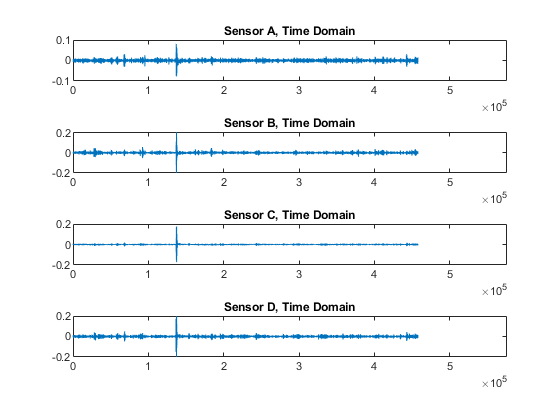


figure()
subplot(4,1,1);
plot(sensor_A); xlim([0 3*fs]);
title("Sensor A, Time Domain (Samples)");
subplot(4,1,2);
plot(sensor_B); xlim([0 3*fs]);
title("Sensor B, Time Domain (Samples)");
subplot(4,1,3);
plot(sensor_C); xlim([0 3*fs]);
title("Sensor C, Time Domain (Samples)");
subplot(4,1,4);
plot(sensor_D); xlim([0 3*fs]);
title("Sensor D, Time Domain (Samples)");

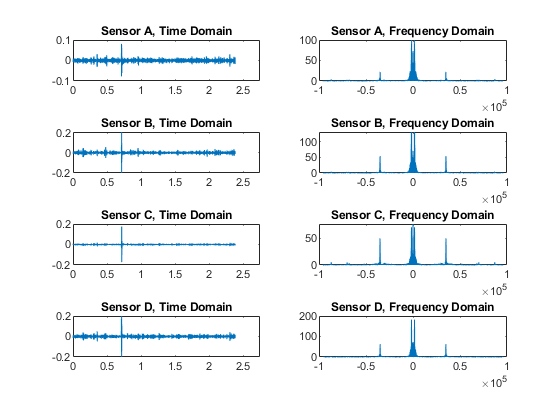



tA = linspace(0,length(sensor_A)/fs,length(sensor_A));
tB = linspace(0,length(sensor_B)/fs,length(sensor_B));
tC = linspace(0,length(sensor_C)/fs,length(sensor_C));
tD = linspace(0,length(sensor_D)/fs,length(sensor_D));

figure()
subplot(4,2,1);
plot(tA,sensor_A); xlim([0 2.75]);
title("Sensor A, Time Domain (Seconds)");
subplot(4,2,3);
plot(tB,sensor_B); xlim([0 2.75]);
title("Sensor B, Time Domain (Seconds)");
subplot(4,2,5);
plot(tC,sensor_C); xlim([0 2.75]);
title("Sensor C, Time Domain (Seconds)");
subplot(4,2,7);
plot(tD,sensor_D); xlim([0 2.75]);
title("Sensor D, Time Domain (Seconds)");


F_sensor_A = fft(sensor_A); % FFT on "sensor_A"
F_sensor_B = fft(sensor_B);
F_sensor_C = fft(sensor_C);
F_sensor_D = fft(sensor_D);


    
fvec_sensor_A = linspace(-fs/2,fs/2,length(sensor_A)); % frequency vector
fvec_sensor_B = linspace(-fs/2,fs/2,length(sensor_B));
fvec_sensor_C = linspace(-fs/2,fs/2,length(sensor_C));
fvec_sensor_D = linspace(-fs/2,fs/2,length(sensor_D));

subplot(4,2,2);
plot(fvec_sensor_A,fftshift(abs(F_sensor_A))); % plot "sensor_A" in frequency domain
title("Sensor A, Frequency Domain");
subplot(4,2,4);
plot(fvec_sensor_B,fftshift(abs(F_sensor_B)));
title("Sensor B, Frequency Domain");
subplot(4,2,6);
plot(fvec_sensor_C,fftshift(abs(F_sensor_C)));
title("Sensor C, Frequency Domain");
subplot(4,2,8);
plot(fvec_sensor_D,fftshift(abs(F_sensor_D)));
title("Sensor D, Frequency Domain");

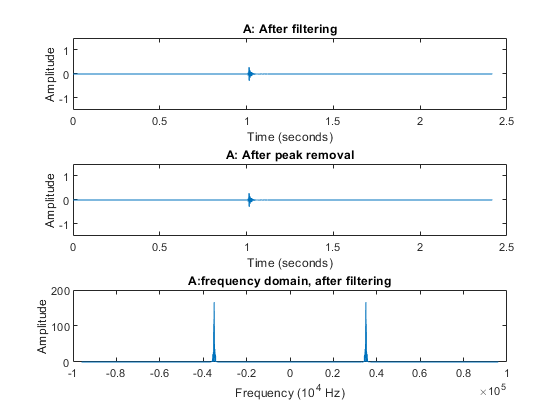

% Filter audio, Remove errant peaks, create plots. 
% Filtered & cleaned audio from each sensor A is: 
% "clean_filtered_A"
% "clean_filtered_B"
% "clean_filtered_C"
% "clean_filtered_D"

% Filter & Plots for sensor A

[b,a] = butter(5,[freq*1000-750, freq*1000+750]/(Fs/2),'bandpass');
    filtered_A = filter(b,a,sensor_A);
    FFT_filtered_A = fftshift(abs(fft(filtered_A)));
    clean_filtered_A = filtered_A;
    
    thresh = .005;
    count = 0;
    
    W = 3000;                               % Window width
    for i = W+1:length(clean_filtered_A)-W
%     for i = 175700:175740                 Manually specified test window
        if abs(clean_filtered_A(i))>thresh
            count=sum(abs(clean_filtered_A(i-W:i+W))>thresh);
            if count<0.2*W
                out2(i)=0;
            end
        end
    end
    
    figure();
    
    subplot(3,1,1);
    plot(t,filtered_A);
    axis([0,2.5, -1.5,1.5]);
    title("A: After filtering");
    ylabel("Amplitude");
    xlabel("Time (seconds)");

    subplot(3,1,2);
    plot(t,clean_filtered_A);
    axis([0,2.5, -1.5,1.5]);
    title("A: After peak removal");
    ylabel("Amplitude");
    xlabel("Time (seconds)");
    
    subplot(3,1,3);
    plot(fvec_sensor_A,FFT_filtered_A);
    title("A:frequency domain, after filtering");
    ylabel("Amplitude");
    xlabel("Frequency (10^4 Hz)");

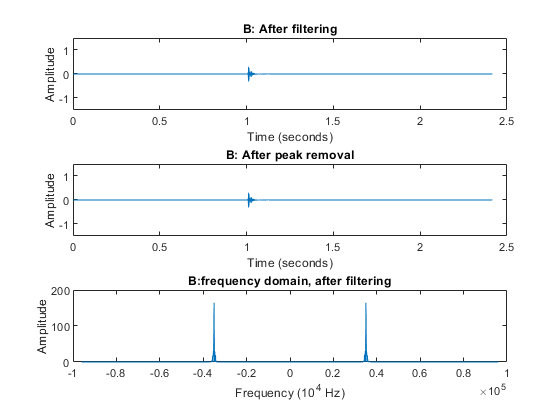

    
% Filter & Plots for sensor B

[b,a] = butter(5,[freq*1000-750, freq*1000+750]/(Fs/2),'bandpass');
    filtered_B = filter(b,a,sensor_B);
    FFT_filtered_B = fftshift(abs(fft(filtered_B)));
    clean_filtered_B = filtered_B;
    
    thresh = .005;
    count = 0;
    
    
    for i = W+1:length(clean_filtered_B)-W
%     for i = 175700:175740
        if abs(clean_filtered_B(i))>thresh
            count=sum(abs(clean_filtered_B(i-W:i+W))>thresh);
            if count<0.2*W
                out2(i)=0;
            end
        end
    end
    
    figure();
    
    subplot(3,1,1);
    plot(t,filtered_B);
    axis([0,2.5, -1.5,1.5]);
    title("B: After filtering");
    ylabel("Amplitude");
    xlabel("Time (seconds)");

    subplot(3,1,2);
    plot(t,clean_filtered_B);
    axis([0,2.5, -1.5,1.5]);
    title("B: After peak removal");
    ylabel("Amplitude");
    xlabel("Time (seconds)");
    
    subplot(3,1,3);
    plot(fvec_sensor_B,FFT_filtered_B);
    title("B:frequency domain, after filtering");
    ylabel("Amplitude");
    xlabel("Frequency (10^4 Hz)");

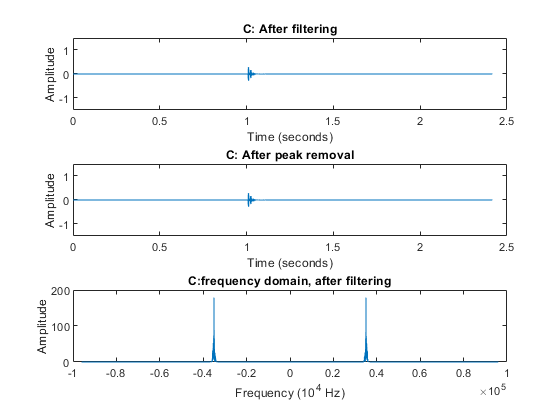


% Filter & Plots for sensor C

[b,a] = butter(5,[freq*1000-750, freq*1000+750]/(Fs/2),'bandpass');
    filtered_C = filter(b,a,sensor_C);
    FFT_filtered_C = fftshift(abs(fft(filtered_C)));
    clean_filtered_C = filtered_C;
    
    thresh = .005;
    count = 0;
    
    
    for i = W+1:length(clean_filtered_C)-W
%     for i = 175700:175740
        if abs(clean_filtered_C(i))>thresh
            count=sum(abs(clean_filtered_C(i-W:i+W))>thresh);
            if count<0.2*W
                out2(i)=0;
            end
        end
    end
    
    figure();
    
    subplot(3,1,1);
    plot(t,filtered_C);
    axis([0,2.5, -1.5,1.5]);
    title("C: After filtering");
    ylabel("Amplitude");
    xlabel("Time (seconds)");

    subplot(3,1,2);
    plot(t,clean_filtered_C);
    axis([0,2.5, -1.5,1.5]);
    title("C: After peak removal");
    ylabel("Amplitude");
    xlabel("Time (seconds)");
    
    subplot(3,1,3);
    plot(fvec_sensor_C,FFT_filtered_C);
    title("C:frequency domain, after filtering");
    ylabel("Amplitude");
    xlabel("Frequency (10^4 Hz)");

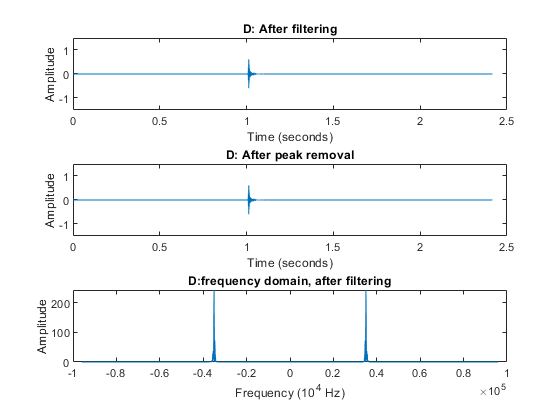


% Filter & Plots for sensor D

[b,a] = butter(5,[freq*1000-750, freq*1000+750]/(Fs/2),'bandpass');
    filtered_D = filter(b,a,sensor_D);
    FFT_filtered_D = fftshift(abs(fft(filtered_D)));
    clean_filtered_D = filtered_D;
    
    thresh = .005;
    count = 0;
    
    
    for i = W+1:length(clean_filtered_B)-W
%     for i = 175700:175740
        if abs(clean_filtered_D(i))>thresh
            count=sum(abs(clean_filtered_B(i-W:i+W))>thresh);
            if count<0.2*W
                out2(i)=0;
            end
        end
    end
    
    figure();
    
    subplot(3,1,1);
    plot(t,filtered_D);
    axis([0,2.5, -1.5,1.5]);
    title("D: After filtering");
    ylabel("Amplitude");
    xlabel("Time (seconds)");

    subplot(3,1,2);
    plot(t,clean_filtered_D);
    axis([0,2.5, -1.5,1.5]);
    title("D: After peak removal");
    ylabel("Amplitude");
    xlabel("Time (seconds)");
    
    subplot(3,1,3);
    plot(fvec_sensor_D,FFT_filtered_D);
    title("D:frequency domain, after filtering");
    ylabel("Amplitude");
    xlabel("Frequency (10^4 Hz)");

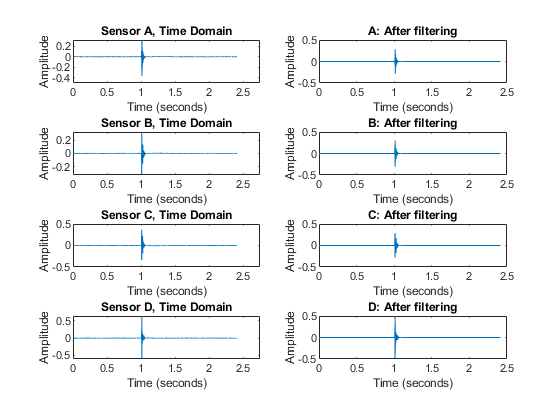

    
    figure() % Time domain pairs, pre and post filter
    
    subplot(4,2,1);
    plot(tA,sensor_A); xlim([0 2.75]);
    title("Sensor A, Time Domain");
    ylabel("Amplitude");
    xlabel("Time (seconds)");

    subplot(4,2,2);
    plot(t,filtered_A);
    axis([0,2.5, -.5,.5]);
    title("A: After filtering");
    ylabel("Amplitude");
    xlabel("Time (seconds)");
    
    subplot(4,2,3);
    plot(tB,sensor_B); xlim([0 2.75]);
    title("Sensor B, Time Domain");
    ylabel("Amplitude");
    xlabel("Time (seconds)");
    
    subplot(4,2,4);
    plot(t,filtered_B);
    axis([0,2.5, -.5,.5]);
    title("B: After filtering");
    ylabel("Amplitude");
    xlabel("Time (seconds)");
    
    subplot(4,2,5);
    plot(tC,sensor_C); xlim([0 2.75]);
    title("Sensor C, Time Domain");
    ylabel("Amplitude");
    xlabel("Time (seconds)");
    
    subplot(4,2,6);
    plot(t,filtered_C);
    axis([0,2.5, -.5,.5]);
    title("C: After filtering");
    ylabel("Amplitude");
    xlabel("Time (seconds)");
    
    subplot(4,2,7);
    plot(tD,sensor_D); xlim([0 2.75]);
    title("Sensor D, Time Domain");
    ylabel("Amplitude");
    xlabel("Time (seconds)");
    
    subplot(4,2,8);
    plot(t,filtered_D);
    axis([0,2.5, -.5,.5]);
    title("D: After filtering");
    ylabel("Amplitude");
    xlabel("Time (seconds)");

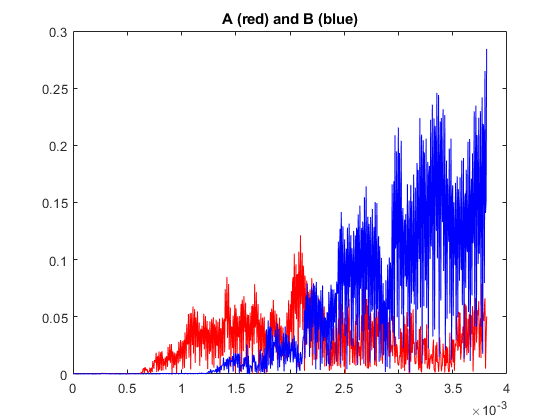


% TDOA algorithm that uses high frequency data from unfiltered audio: 


%   Sensor Pair A & B:



% We initially guess that unfiltered audio begins to show amplitude 100 us
% before the clean filtered audio.
%
% There are .192 samples per microsecond. 100 us = 521 samples.
%
% Sensor_A (unfiltered audio) should begin to show a high frequency amplitude spike in the window of
% Sensor_A(tempA-521:tempA+521)
%
% We now know that Sensor_A(tempA-521:tempA+521) includes too much low
% frequency noise, and will use TDOAsensorA =
% abs(sensor_A(tempA-TDOA_leftedge:tempA+TDOA_rightedge)).

tempA = find(clean_filtered_A >.001, 1); % Find the array index of clean_filtered_A
                                        % where amplitude first begins to climb.

TDOA_leftedge  = 210;
TDOA_rightedge = 521;

TDOAsensorA = abs(sensor_A(tempA-TDOA_leftedge:tempA+TDOA_rightedge));

% Repeat for sensor_B

TDOAsensorB = abs(sensor_B(tempA-TDOA_leftedge:tempA+TDOA_rightedge));

% Plot TDOAsensorA & TDOAsensorB together:

t_TDOApair = linspace(0,length(TDOAsensorA)/192000,length(TDOAsensorA)); % time vector for new shortened arrays

figure()
plot(t_TDOApair,TDOAsensorA,'r'); hold on; plot(t_TDOApair,TDOAsensorB,'b'); hold off; title('A (red) and B (blue)');

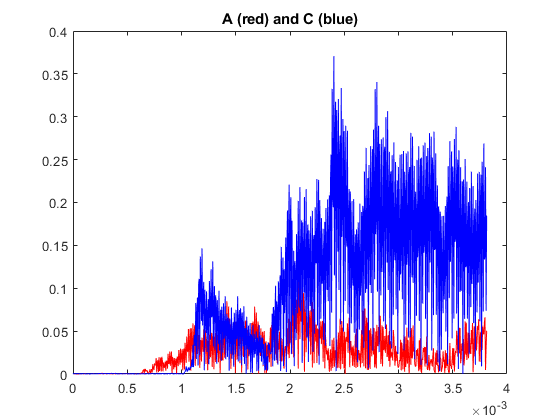


% Can use plot to define an amplitude threshold and find the indices and time values
% when both A & B cross that threshold.

DiffThreshA = .15*(max(TDOAsensorA));
DiffThreshB = .15*(max(TDOAsensorB));

TDOAindex_A = find(TDOAsensorA>DiffThreshA,1);
TDOAindex_B = find(TDOAsensorB>DiffThreshB,1);

TDOA_time_A = t_TDOApair(TDOAindex_A);
TDOA_time_B = t_TDOApair(TDOAindex_B);

TDOA_time_AB = TDOA_time_A-TDOA_time_B;

tau_AB = round((TDOA_time_A-TDOA_time_B)*fs);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Sensor pair A & C:

% Repeat for sensor_C

TDOAsensorC = abs(sensor_C(tempA-TDOA_leftedge:tempA+TDOA_rightedge));

% Plot TDOAsensorA & TDOAsensorC together:

figure()
plot(t_TDOApair,TDOAsensorA,'r'); hold on; plot(t_TDOApair,TDOAsensorC,'b'); hold off; title('A (red) and C (blue)');

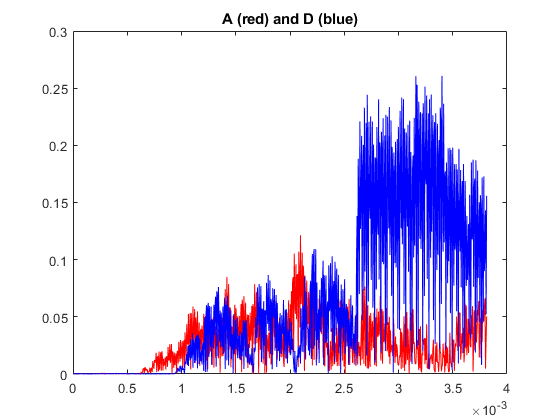


% Can use plot to define an amplitude threshold and find the indices and time values
% when both A & B cross that threshold.

DiffThreshA = .15*(max(TDOAsensorA));
DiffThreshC = .15*(max(TDOAsensorC));

TDOAindex_A = find(TDOAsensorA>DiffThreshA,1);
TDOAindex_C = find(TDOAsensorC>DiffThreshC,1);

TDOA_time_A = t_TDOApair(TDOAindex_A);
TDOA_time_C = t_TDOApair(TDOAindex_C);

TDOA_time_AC = TDOA_time_A-TDOA_time_C;

tau_AC = round((TDOA_time_A-TDOA_time_C)*fs);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Sensor pair A & D

% Repeat for sensor_D

TDOAsensorD = abs(sensor_D(tempA-TDOA_leftedge:tempA+TDOA_rightedge));

% Plot TDOAsensorA & TDOAsensorD together:

figure()
plot(t_TDOApair,TDOAsensorA,'r'); hold on; plot(t_TDOApair,TDOAsensorD,'b'); hold off; title('A (red) and D (blue)');


% Can use plot to define an amplitude threshold and find the indices and time values
% when both A & B cross that threshold.-

DiffThreshA = .15*(max(TDOAsensorA));
DiffThreshD = .15*(max(TDOAsensorD));

TDOAindex_A = find(TDOAsensorA>DiffThreshA,1);
TDOAindex_D = find(TDOAsensorD>DiffThreshD,1);

TDOA_time_A = t_TDOApair(TDOAindex_A);
TDOA_time_D = t_TDOApair(TDOAindex_D);

TDOA_time_AD = TDOA_time_A-TDOA_time_D;

tau_AD = round((TDOA_time_A-TDOA_time_D)*fs);

% End unfiltered audio time-lag component

% Begin fine tuning TDOA values with Cross Correlation

sensor_A = data(:,1);
sensor_B = data(:,2);
sensor_C = data(:,3);
sensor_D = data(:,4);

w=clean_filtered_A; 
x=clean_filtered_B;
y=clean_filtered_C;
z=clean_filtered_D;

lA = length(w);
lB = length(x);
lC = length(y);
lD = length(z);

samples1 = 1:min(lA,lB);
samples2 = 1:min(lA,lC);
samples3 = 1:min(lA,lD);


[C1, lag1] = xcorr(w(samples1), x(samples1), 155);
[C2, lag2] = xcorr(w(samples2), y(samples2), 155);
[C3, lag3] = xcorr(w(samples3), z(samples3), 135);

%normalizing XCorr
C1 = C1/max(C1);
C2 = C2/max(C2);
C3 = C3/max(C3);

WINDOW = ceil(fs/(2*1000*freq)*1.5);

n1 = ceil(length(C1)/2);
n2 = ceil(length(C2)/2);
n3 = ceil(length(C3)/2);

    
C1sub2 = C1((tau_AB + n1 - WINDOW):(tau_AB + n1 + WINDOW));
idx_AB2 = find(C1sub2==max(C1sub2))+tau_AB+n1-WINDOW;

C2sub2 = C2((tau_AC + n2 - WINDOW):(tau_AC + n2 + WINDOW));
idx_AC2 = find(C2sub2==max(C2sub2))+tau_AC+n2-WINDOW;

C3sub2 = C3((tau_AD + n3 - WINDOW):(tau_AD + n3 + WINDOW));
idx_AD2 = find(C3sub2==max(C3sub2))+tau_AD+n3-WINDOW;


tau_AB2 = lag1(idx_AB2);
tau_AC2 = lag1(idx_AC2);
tau_AD2 = lag1(idx_AD2);

C1sub = C1((tau_AB2 + n1 - WINDOW):(tau_AB2 + n1 + WINDOW));
idx_AB = find(C1sub==max(C1sub))+tau_AB2+n1-WINDOW;

C2sub = C2((tau_AC2 + n2 - WINDOW):(tau_AC2 + n2 + WINDOW));
idx_AC = find(C2sub==max(C2sub))+tau_AC2+n2-WINDOW;

C3sub = C3((tau_AD2 + n3 - WINDOW):(tau_AD2 + n3 + WINDOW));
idx_AD = find(C3sub==max(C3sub))+tau_AD2+n3-WINDOW;


adjusted_tdoa_seconds_A_B = lag1(idx_AB)/fs
adjusted_tdoa_seconds_A_C = lag1(idx_AC)/fs
adjusted_tdoa_seconds_A_D = lag1(idx_AD)/fs


% Multilateration now needs to take the above three
% adjusted_tdoa_seconds_A_X" variables as inputs





%% Speed of sound in water
c = 1500;        % m/s
%% Location of the hydrophones
% Sensor A is at the origin. Do not change this.
xA = 0;
yA = 0;
zA = 0;

xB = -.838;
yB = -.813;
zB = .254;


xC = -.838;
yC = -.406;
zC = .813;

xD = -.838;
yD = -.406;
zD = .419;



% Solve Equations

  Eq1: tauB = (1/c) * ( sqrt( (x-xB)^2 + (y-yB)^2 + (z-zB)^2 ) - sqrt(x^2 + y^2 + z^2) )
  Eq2: tauC = (1/c) * ( sqrt( (x-xC)^2 + (y-yC)^2 + (z-zC)^2 ) - sqrt(x^2 + y^2 + z^2) )
  Eq3: tauD = (1/c) * ( sqrt( (x-xD)^2 + (y-yD)^2 + (z-zD)^2 ) - sqrt(x^2 + y^2 + z^2) )

  Unknown 1: x
  Unknown 2: y
  Unknown 3: z

syms x y z

eq1 = -round(adjusted_tdoa_seconds_A_B, 5) == (1/c) * ( sqrt( (x-xB)^2 + (y-yB)^2 + (z-zB)^2 ) - sqrt(x^2 + y^2 + z^2) );
eq2 = -round(adjusted_tdoa_seconds_A_C, 5) == (1/c) * ( sqrt( (x-xC)^2 + (y-yC)^2 + (z-zC)^2 ) - sqrt(x^2 + y^2 + z^2) );
eq3 = -round(adjusted_tdoa_seconds_A_D, 5) == (1/c) * ( sqrt( (x-xD)^2 + (y-yD)^2 + (z-zD)^2 ) - sqrt(x^2 + y^2 + z^2) );

sol = solve([eq1, eq2, eq3], [x, y, z]);

xSol = real(double(sol.x));
ySol = real(double(sol.y));
zSol = real(double(sol.z));

if length(xSol) == 1
    solutions = [xSol,ySol,zSol,xSol,ySol,zSol]
    recalculate = 0; 
elseif isempty(xSol) 
    solutions = [0,0,0,0,0,0]; %% Solution using xCorr-adjusted TDOA
    recalculate = 1; 
else    
    solutions = [xSol(1) ySol(1) zSol(1) xSol(2) ySol(2) zSol(2)]
    recalculate = 1; 
end

syms x y z

eq1 = -round(TDOA_time_AB, 5) == (1/c) * ( sqrt( (x-xB)^2 + (y-yB)^2 + (z-zB)^2 ) - sqrt(x^2 + y^2 + z^2) );
eq2 = -round(TDOA_time_AC, 5) == (1/c) * ( sqrt( (x-xC)^2 + (y-yC)^2 + (z-zC)^2 ) - sqrt(x^2 + y^2 + z^2) );
eq3 = -round(TDOA_time_AD, 5) == (1/c) * ( sqrt( (x-xD)^2 + (y-yD)^2 + (z-zD)^2 ) - sqrt(x^2 + y^2 + z^2) );

sol = solve([eq1, eq2, eq3], [x, y, z]);

xSol = double(sol.x);
ySol = double(sol.y);
zSol = double(sol.z);

if length(xSol) == 1
    solutions2 = [xSol,ySol,zSol,xSol,ySol,zSol]
    recalculate = 0; 
elseif isempty(xSol) 
    solutions2 = [0,0,0,0,0,0]; %% Solution using orignal TDOA, no XCorr
    recalculate = 1; 
else    
    solutions2 = [xSol(1) ySol(1) zSol(1) xSol(2) ySol(2) zSol(2)]
    recalculate = 1; 
end
